

%% Instantiate video device, face detector, and KLT object tracker
videoReader = VideoReader('Face.mp4');

faceDetector = vision.CascadeObjectDetector(); % Finds faces by default
tracker = MultiObjectTrackerKLT;

%% Get a frame for frame-size information
videoFrame  = readFrame(videoReader);
frameSize = size(videoFrame);

%% Create a video player instance
videoPlayer  = vision.VideoPlayer('Position',[200 100 fliplr(frameSize(1:2)+30)]);

%% Iterate until we have successfully detected a face
bboxes = [];
while isempty(bboxes)
    framergb = readFrame(videoReader);
    videoframe = rgb2gray(framergb);
    bboxes = faceDetector.step(videoframe);
end
tracker.addDetections(videoframe, bboxes);

%% And loop until the player is closed
frameNumber = 0;
keepRunning = true;
disp('Press Ctrl-C to exit...');

Press Ctrl-C to exit...


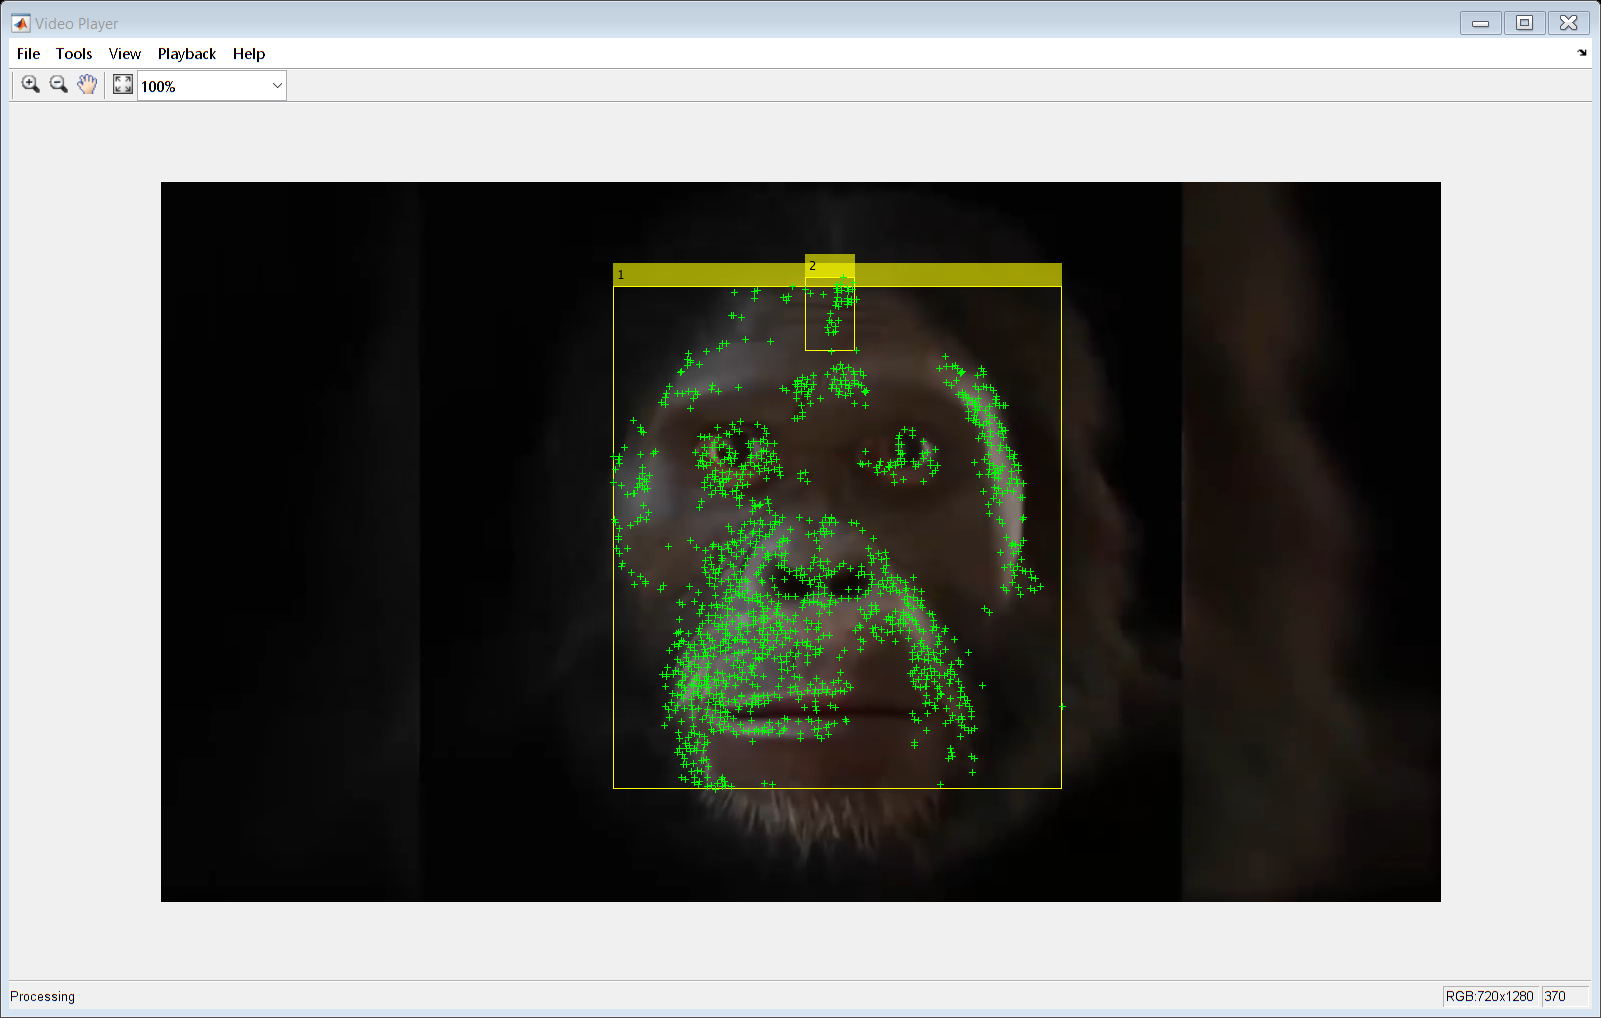

Index in position 1 exceeds array bounds (must not exceed 1).

Error in MultiObjectTrackerKLT/addDetections (line 123)
                    this.BoxLabels = [this.BoxLabels; Labels(i, :)];

while keepRunning
    
    framergb = readFrame(videoReader);
    videoframe = rgb2gray(framergb);
    
    if mod(frameNumber, 10) == 0
        % (Re)detect faces.
        %
        % NOTE: face detection is more expensive than imresize; we can
        % speed up the implementation by reacquiring faces using a
        % downsampled frame:
        % bboxes = faceDetector.step(frame);
        bboxes = 2 * faceDetector.step(imresize(videoframe, 0.5));
        if ~isempty(bboxes)
            tracker.addDetections(videoframe, bboxes);
        end
    else
        % Track faces
        tracker.track(videoframe);
    end
    
    % Display bounding boxes and tracked points.
    displayFrame = insertObjectAnnotation(framergb, 'rectangle',...
        tracker.Bboxes, tracker.BoxIds);
    displayFrame = insertMarker(displayFrame, tracker.Points);
    videoPlayer.step(displayFrame);
    
    frameNumber = frameNumber + 1;
end


%% Clean up
release(videoPlayer);